% =========================================================================
% SCRIPT : Recherche dynamique et Comparaison de X analyses pour chaque K
% =========================================================================

% 1. Définir le dossier racine et le motif de recherche
dossier_principal = "E:\Data\Aurelie\analysis\final_analysis_sept2024\old\oldanalysis";

% =========================================================================
% SCRIPT : Comparaison globale (Similarité Jaccard + NClini vs Final)
% =========================================================================

% 1. Définir le dossier racine et le motif de recherche
% dossier_principal = 'E:\Data\Aurelie\analysis\March2026\nocues\test_stability';
motif_recherche = '*411582_230320_plane0*';

% Trouver automatiquement tous les dossiers correspondants
contenu = dir(fullfile(dossier_principal, motif_recherche));
dossiers_trouves = contenu([contenu.isdir]); % Garder uniquement les dossiers

nb_analyses_initial = length(dossiers_trouves);
fprintf('Nombre de dossiers trouvés : %d\n', nb_analyses_initial);

Nombre de dossiers trouvés : 19



if nb_analyses_initial < 2
    error('Il faut au moins 2 dossiers correspondants pour faire une comparaison.');
end

% 2. Chargement des données
assemblies = cell(nb_analyses_initial, 1);
noms_analyses = cell(nb_analyses_initial, 1);
analyses_valides = true(nb_analyses_initial, 1);
nb_clusters_par_analyse = zeros(nb_analyses_initial, 1);
ncl_ini_par_analyse = NaN(nb_analyses_initial, 1); % Rempli de NaN par défaut
labels_analyses = cell(nb_analyses_initial, 1);

for d = 1:nb_analyses_initial
    noms_analyses{d} = dossiers_trouves(d).name;
    fichier = fullfile(dossier_principal, noms_analyses{d}, 'results.mat');
    
    if isfile(fichier)
        % Vérifier quelles variables existent dans le fichier avant de charger
        infos_fichier = whos('-file', fichier);
        noms_variables = {infos_fichier.name};
        
        if ismember('NClini', noms_variables)
            data = load(fichier, 'assemblyortho', 'NClini');
            ncl_ini_par_analyse(d) = data.NClini;
            has_nclini = true;
        else
            data = load(fichier, 'assemblyortho');
            has_nclini = false;
        end
        
        assemblies{d} = data.assemblyortho;
        nb_clusters_par_analyse(d) = length(assemblies{d});
        labels_analyses{d} = sprintf('A%d', d);
        
        if has_nclini
            fprintf('Analyse %d chargée : NClini = %d, Clusters finaux = %d.\n', ...
                d, ncl_ini_par_analyse(d), nb_clusters_par_analyse(d));
        else
            fprintf('Analyse %d chargée : %d Clusters finaux (NClini absent).\n', ...
                d, nb_clusters_par_analyse(d));
        end
    else
        warning('Fichier results.mat introuvable dans : %s', noms_analyses{d});
        analyses_valides(d) = false;
    end
end

Analyse 15 chargée : 4 Clusters finaux (NClini absent).


Analyse 17 chargée : 5 Clusters finaux (NClini absent).


Analyse 18 chargée : 3 Clusters finaux (NClini absent).


Analyse 19 chargée : 4 Clusters finaux (NClini absent).



% Filtrer pour ne garder que les analyses valides
assemblies = assemblies(analyses_valides);
nb_clusters_par_analyse = nb_clusters_par_analyse(analyses_valides);
ncl_ini_par_analyse = ncl_ini_par_analyse(analyses_valides);
labels_analyses = labels_analyses(analyses_valides);
nb_analyses = length(assemblies);

if nb_analyses < 2
    error('Pas assez de fichiers results.mat valides trouvés pour comparer.');
end

% 3. Calculer la similarité de Jaccard pour toutes les paires
nb_paires = nchoosek(nb_analyses, 2); 
similarites_paires = zeros(nb_paires, 1);
labels_paires = cell(nb_paires, 1);

idx_paire = 1;
for i = 1:nb_analyses-1
    for j = (i+1):nb_analyses
        assembly_1 = assemblies{i};
        assembly_2 = assemblies{j};
        
        matrice_jaccard = zeros(length(assembly_1), length(assembly_2));
        
        for c1 = 1:length(assembly_1)
            for c2 = 1:length(assembly_2)
                set_1 = assembly_1{c1};
                set_2 = assembly_2{c2};
                intersection = length(intersect(set_1, set_2));
                union_12 = length(union(set_1, set_2));
                matrice_jaccard(c1, c2) = intersection / max(union_12, 1);
            end
        end
        
        % Meilleur match pour chaque cluster de l'analyse 1
        meilleurs_matchs = max(matrice_jaccard, [], 2);
        
        % Sauvegarde
        similarites_paires(idx_paire) = mean(meilleurs_matchs);
        labels_paires{idx_paire} = sprintf('A%d vs A%d', i, j);
        idx_paire = idx_paire + 1;
    end
end

moyenne_globale = mean(similarites_paires);
fprintf('\n--- RÉSULTATS ---\nSimilarité moyenne globale : %.2f%%\n', moyenne_globale * 100);


--- RÉSULTATS ---
Similarité moyenne globale : 65.68%


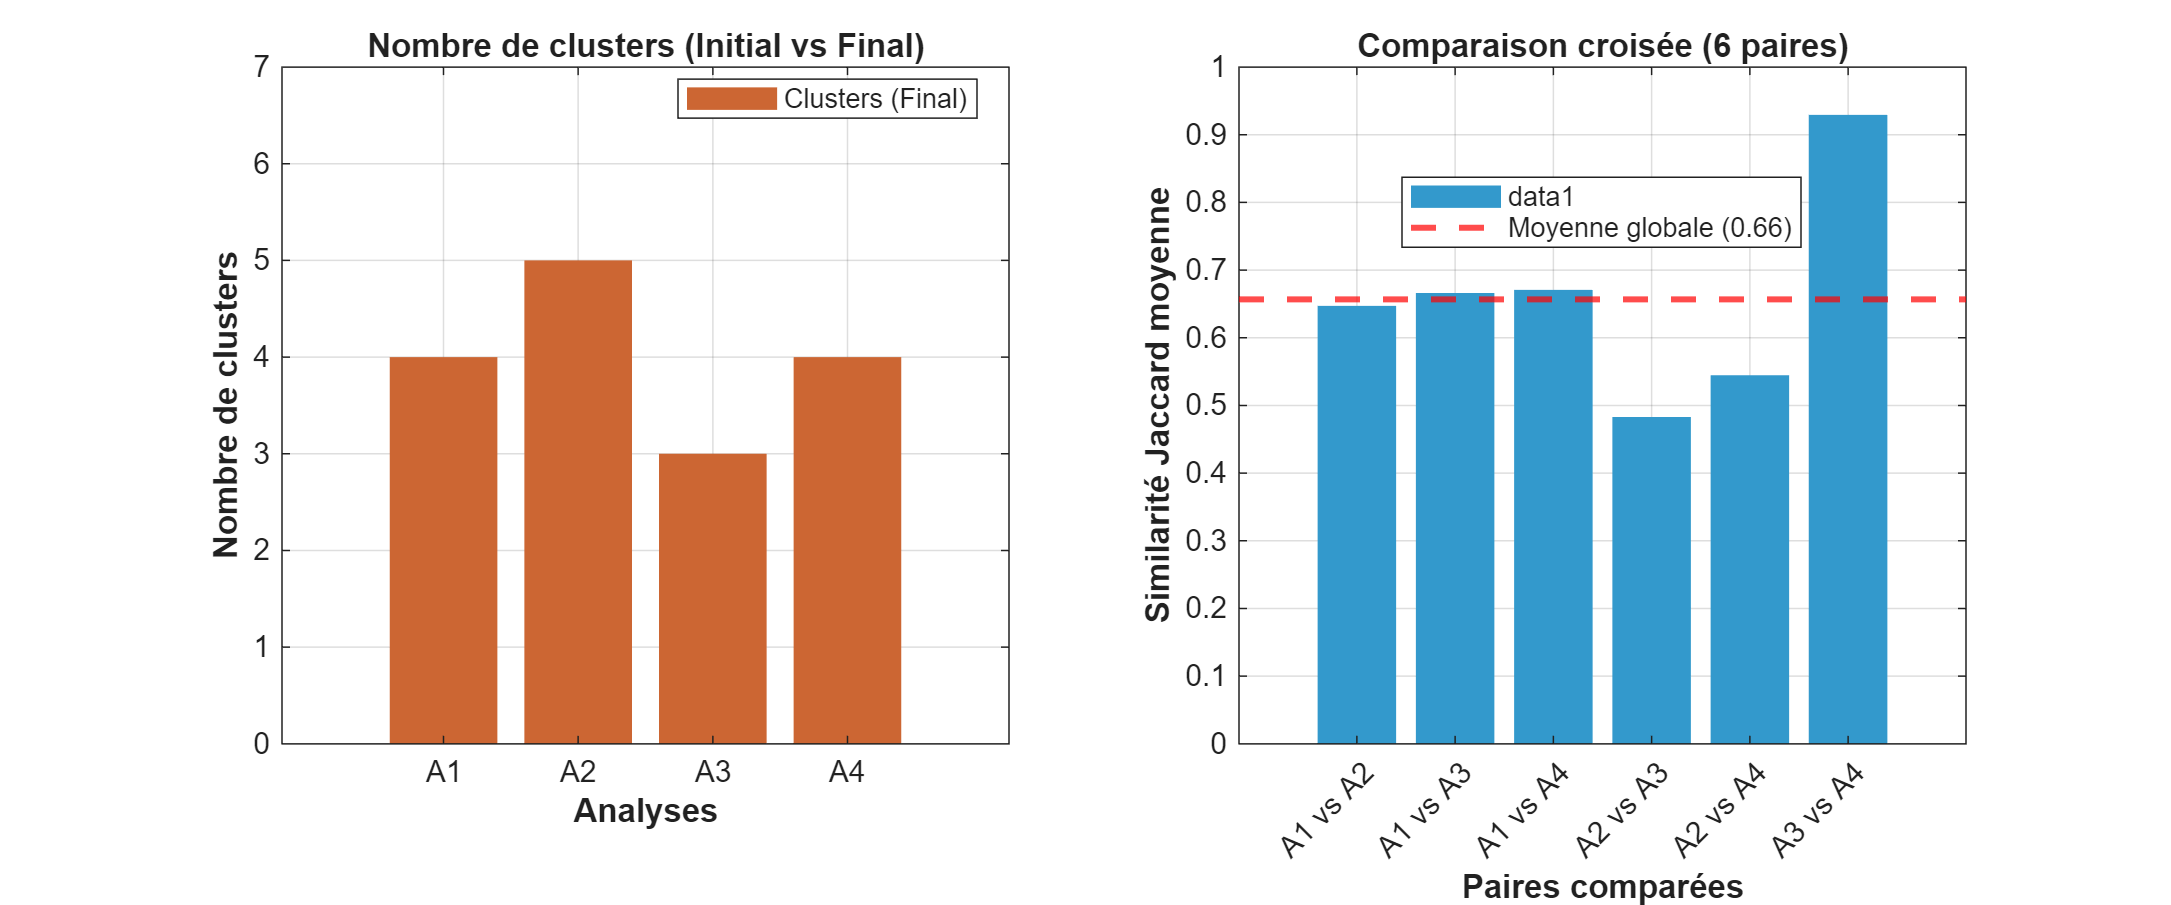


% =========================================================================
% Affichage Graphique (Dashboard avec 2 subplots)
% =========================================================================
figure('Name', 'Bilan des analyses', 'Color', 'w', 'Position', [100 100 1200 500]);

% --- GRAPHIQUE 1 : Nombre de clusters par analyse ---
subplot(1, 2, 1);
if any(~isnan(ncl_ini_par_analyse))
    % Si NClini est présent dans au moins un fichier : barres groupées
    b = bar(1:nb_analyses, [ncl_ini_par_analyse, nb_clusters_par_analyse], 'grouped');
    b(1).FaceColor = [0.6 0.6 0.6]; % Gris pour NClini
    b(2).FaceColor = [0.8 0.4 0.2]; % Orange pour Final
    legend('NClini (Initial)', 'Clusters (Final)', 'Location', 'best');
    max_y = max(max(ncl_ini_par_analyse, [], 'omitnan'), max(nb_clusters_par_analyse));
else
    % Si NClini est totalement absent : barres simples
    bar(1:nb_analyses, nb_clusters_par_analyse, 'FaceColor', [0.8 0.4 0.2], 'EdgeColor', 'none');
    legend('Clusters (Final)', 'Location', 'best');
    max_y = max(nb_clusters_par_analyse);
end
hold on;

xticks(1:nb_analyses);
xticklabels({'A1' 'A2' 'A3' 'A4'});
xlabel('Analyses', 'FontWeight', 'bold');
ylabel('Nombre de clusters', 'FontWeight', 'bold');
title('Nombre de clusters (Initial vs Final)');
ylim([0, max_y + 2]); % Adapte l'axe Y dynamiquement
grid on;
hold off;

% --- GRAPHIQUE 2 : Similarité Jaccard entre les paires ---
subplot(1, 2, 2);
bar(1:nb_paires, similarites_paires, 'FaceColor', [0.2 0.6 0.8], 'EdgeColor', 'none');
hold on;
yline(moyenne_globale, 'r--', 'LineWidth', 2, ...
    'DisplayName', sprintf('Moyenne globale (%.2f)', moyenne_globale));

xticks(1:nb_paires);
xticklabels(labels_paires);

xtickangle(45);
xlabel('Paires comparées', 'FontWeight', 'bold');
ylabel('Similarité Jaccard moyenne', 'FontWeight', 'bold');
title(sprintf('Comparaison croisée (%d paires)', nb_paires));
ylim([0 1]);
grid on;
legend('Location', 'best');
hold off;